% clear;

Исходные данные 

betta alpha r

ABC - из прошлой работы №8

A = [2 6; 1 0];
B = [4; 1];
C = [2 0];
alpha = 2.9;
beta = 2.6;
r = abs(beta)/1.5;

## **1.Вычислить параметры матрицы линейных стационарных обратных связей ****K****.**

### ***1.1 Обеспечение желаемой степени сходимости***

Решаем уравнение типа Риккати:

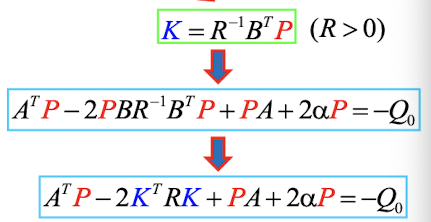

R = 1; v = 2; I = eye(2); Q = I;

P – симметрическая квадратная матрица, 

Q – симметрическая матрица штрафов на вектор состояния объекта, по крайней мере, положительно полуопределенная, 

R – квадратная строго положительно-определенная матрица размером, определяющая штраф на управления, 

v – параметр модификации, принимающий значения в пределах от 0 до 2.

**iqr - **

[ K, P ] = lqr (A+alpha*eye(2), B, Q, R/2, []);
K = inv(R)*B'*P;
P, K % вывод  

P =    30.8201 -128.1178
 -128.1178  540.7551


K =    -4.8374   28.2840


Проверка

F = A - B*K

F =    21.3497 -107.1359
    5.8374  -28.2840


eig(F) % собственные числа ма

ans =   -3.4671 + 3.0858i
  -3.4671 - 3.0858i


### ***1.2 Обеспечение качественной экспоненциальной устойчивости***

Решаем систему уравнений

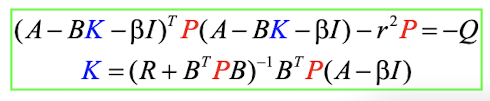

Q = eye(2); R = 0;
syms p11 p12 p22 k1 k2;
P = [p11 p12; p12 p22];
k = [k1 k2];
eqn1 = ((A-B*k-beta*eye(2))' *P*(A-B*k-beta*eye(2)) - r^2*P == -Q);
eqn2 = (k == inv(R+B'*P*B)*B'*P*(A-beta*eye(2)));
sol = solve([eqn1; eqn2], [p11, p12, p22, k1, k2])

sol = struct with fields:
    p11: [4×1 sym]
    p12: [4×1 sym]
    p22: [4×1 sym]
     k1: [4×1 sym]
     k2: [4×1 sym]


Проверяем ссколько решений выдает Матлаб

сколько решений относительно уравнения типа Рекатти для обеспечения качественной экспоненой устойчивости 

p11Sol = double(sol.p11) % 4 решения

p11Sol =     0.3034
  111.3347
  111.3347
  140.4519


p12Sol = double(sol.p12);
p22Sol = double(sol.p22);

for i = 1 : 4  % тут столько сколько и решений 
    % команда для расчета  собственных чисел
    eig([p11Sol(i) p12Sol(i);  p12Sol(i)  p22Sol(i) ]) 
end

ans =    -0.0710
    0.3328


ans = 	1.0e+03 *

         0
    1.8927


ans = 	1.0e+03 *

         0
    1.8927


ans = 	1.0e+03 *

    0.0003
    1.9215


матрица Р должна быть определенная (смотрим какая из них положительно опреденная)

смотрим какой  подходит,  должен быть полностью  оппределенный

for i =1:4
    K = double([sol.k1(i) sol.k2(i)])
    eig(A-B*K)
end

K =    -0.0730    1.2255


ans =     2.6000
   -1.5335


K = 	1.0e+66 *

   -0.8760    1.1336


ans = 	1.0e+66 *

    2.3702
         0


K = 	1.0e+66 *

   -0.8760    1.1336


ans = 	1.0e+66 *

    2.3702
         0


K =    -7.9082   29.1598


ans =     2.6000
    1.8731


K = double([sol.k1(4) -sol.k2(4)])

K =    -7.9082  -29.1598


eig(A-B*K) % должны получиться данные из условия

ans =    64.5249
   -1.7322


r, beta

r = 1.7333

beta = 2.6000

### **2. Проведем моделирование системы в Simulink**

*Схема моделирования замкнутой системы:*